# Lifting Line Model for Rotors

This program simulates rotors by combining Lifting Line and Blade Element theory. Below you find all the inputs necessary for this program. It is possible to simulate 2 rotors next to eachother. If you choose to only simulate one rotor, then the rotors distance and phase difference are ignored. The amount of blades that is specified, is per rotor. The rotor distance variable is the amount of diameters between the centers of the rotors. It can be chosen to model the expansion of the wake as well, this is based on the conservation of mass.

The thrust and power coefficients are calculated after the run. Next to this, several variables can be plotted, such as the angle of attack over the blades, the induction factors a and a', and several others.

## Input


%% Setting up system parameters and variables. 
Uinf    = 10;                % Freestream velocity [m/s]
radius  =100 ;         % radius [m]
Nblades = 3;                % Number of blades [-]
Nrotors = 2;                % Number of rotors [-]
Drotors = 1*2*radius;% distance between rotors [m] 


rotorPhase = 0; % phase difference [deg]
TSR        = 10; % Tip speed ratio[-]
polar      ="polar DU95W180.xlsx" ;      % airfoil polar
N          = 10;   % Number of spanwise elements [-]
LWake      = 300; % Length of the wake [m]

deltaDeg  = 30;                          % discretization angle [deg]
rRoot     = 0.2;                         % r/R root [-]
rTip      = 1.0;                         % r/R tip[-]

aWake  = 0.3;                            % initial induction based on BEM results [-]
weight = 0.3;                            % weight of the new solution


distType  = "uniform";            % distribution type "uniform"/"cosine"
propType  = "turb"; %type of rotor "turb"/"prop"         
chord     = @(r) 3*(1-r)+1; %chord distribution [m]
twist     = @(r) 14*(1-r)-2; %twist distribution [m]
expansion =true;                   % modelling of expansion or not

 


%create the model object
LL = LiftingLine(Uinf,N,radius,rTip,rRoot,TSR,distType,propType,...
                 polar,Nblades,Nrotors,Drotors,rotorPhase,chord,twist);
             
%Obtain coordinates, control points and r/R (for plotting)
[coordinates,cp,r_cp] = LL.modelSetUp(LWake,aWake,deltaDeg,expansion);

%Obtain unit circulation induced velocities
[u,v,w] = LL.getIndVel(coordinates,cp);

%solve the system
results = LL.solveSystem(u,v,w,cp,weight);

Number of iterations: 28



CT = LL.getCT(r_cp,results);
CP = LL.getCP(r_cp,results);

disp("Power coefficient:  CP = " +num2str(sum(CP(1:length(r_cp)))) + " [-]");

Power coefficient:  CP = 0.25723 [-]


disp("Thrust coefficient: CT = " +num2str(sum(CT(1:length(r_cp)))) + " [-]");

Thrust coefficient: CT = 0.60477 [-]


## Wake and rotor geometry

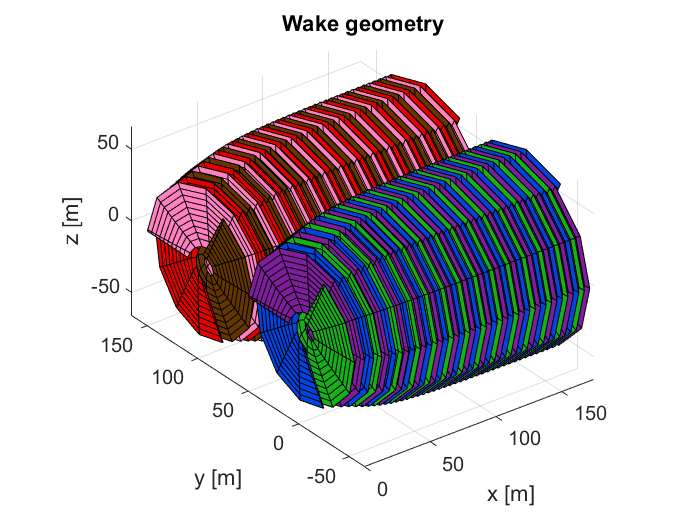

%plot the wake and rotor configuration
colors = readtable("colors.csv",'PreserveVariableNames',true);

LL.plotWake(coordinates,colors);
title("Wake geometry")

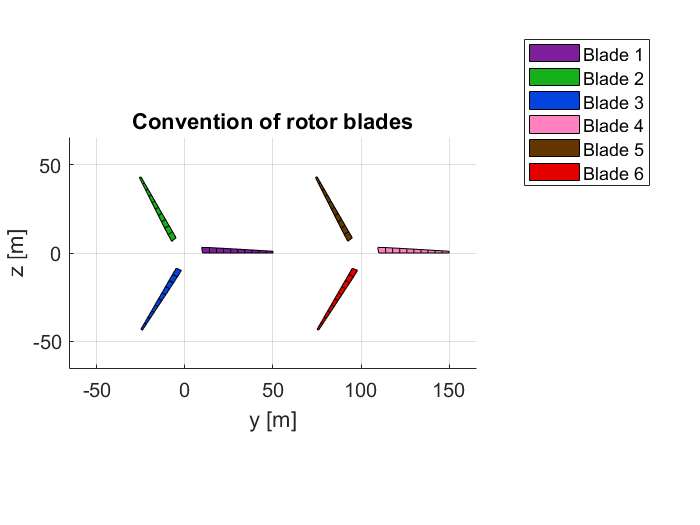

LL.plotRotors(coordinates,colors);
title("Convention of rotor blades")

## Result figures

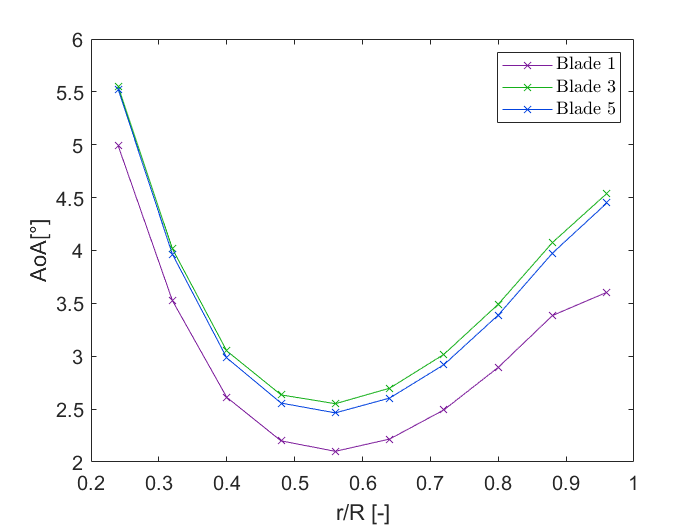


labels = ["a [-]","a' [-]","C_n [-]","C_t [-]",...
          "Inflow angle [" + char(176) + "]",...
          "AoA[" + char(176) + "]","\Gamma [-]","C_l [-]"];

names  = fieldnames(results);
name   = "AoA";
blades = [1:2:6];

  

%check if it is possible to plot

if max(blades)>Nrotors*Nblades
    disp("Error: Highest blade number is higher than total amount of blades.")
    blade = min(Nrotors*Nblades,max(blades));
else
    values = results.(name);
    ylab   = labels(names==name);
    leg    = [];
    LL.plotResults(blades,r_cp,values,ylab,leg,colors);
end